本代码演示计算前馈补偿器函数的使用

详见https://zhuanlan.zhihu.com/p/280484938

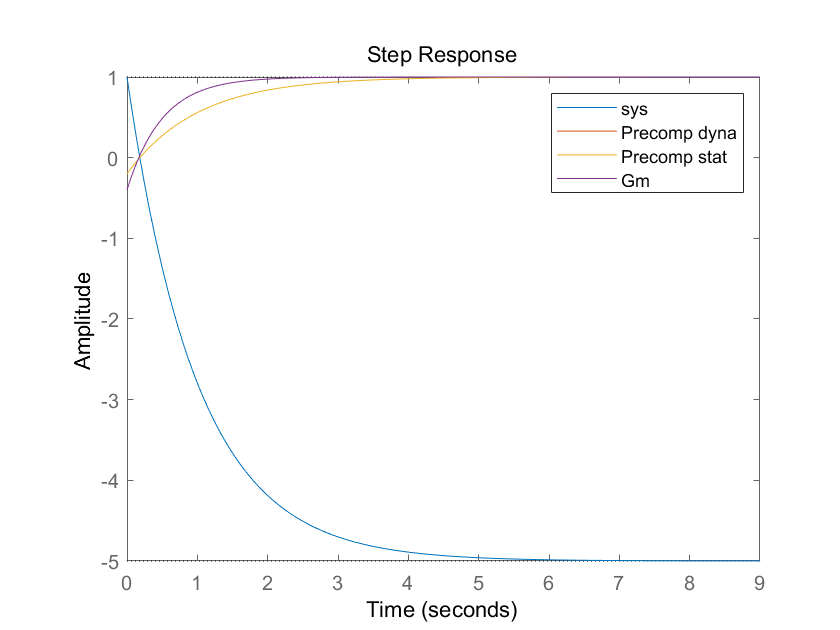

% 传递函数

s = tf('s');
G = (s-5)*(s+2)/(s+1)/(s+2);% 非最小相位+稳定系统

%时间常数的影响
[Precomp1,precomp_stat1,Gm1] = Precompensateur(G,0.5);

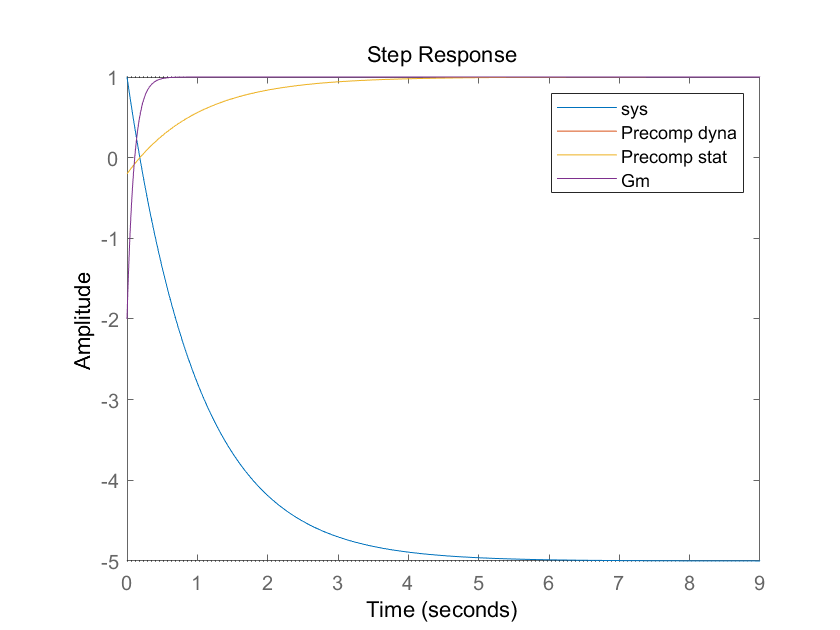

[Precomp2,precomp_stat2,Gm2] = Precompensateur(G,0.1);

% 时间常数只用于计算动态前馈补偿器，越小响应越快

% 状态方程
A = [ -8.0000   -5.2500   -2.2500
    4.0000         0         0
         0    2.0000         0];
B = [4;0;0];
C = [ 0    2.1875    5.4688];
D = 0;
G2 = ss(A,B,C,D)


G2 =
 
  A = 
          x1     x2     x3
   x1     -8  -5.25  -2.25
   x2      4      0      0
   x3      0      2      0
 
  B = 
       u1
   x1   4
   x2   0
   x3   0
 
  C = 
          x1     x2     x3
   y1      0  2.188  5.469
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



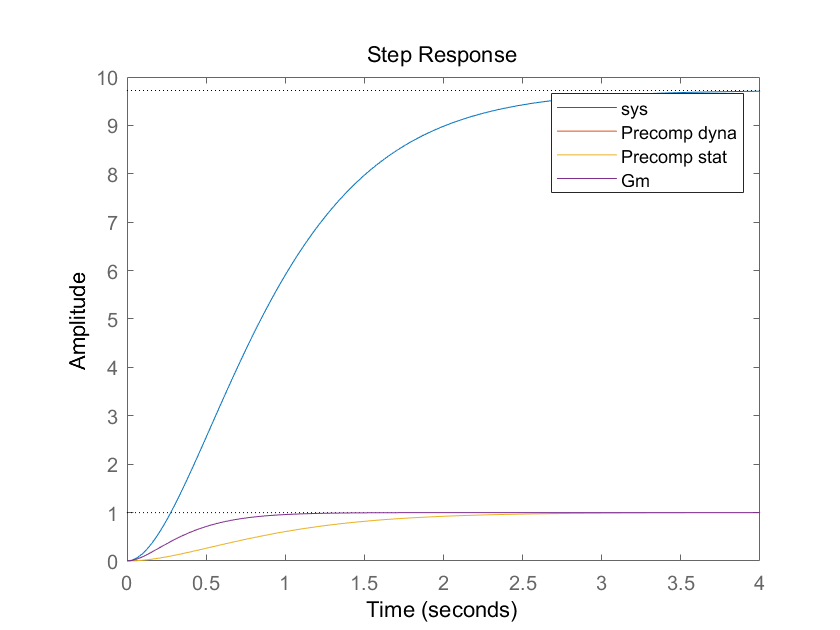


[Precomp3,precomp_stat3,Gm3] = Precompensateur(G2,0.2);